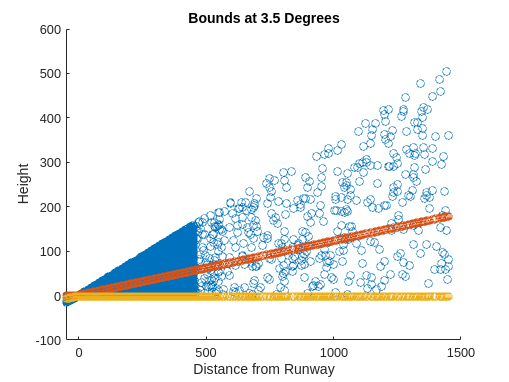

clear variables; close all; clc;
runway_height = 376;
dist_const = 1;
data = readtable("/home/achadbo/Desktop/dataWPI_1500_50_10/states.csv");
x = data.x;
h = data.h - runway_height;
y = data.y;

slope = tand(3.5);
slope_x = x.*slope;
% slope_x_subset = x(x >= 500).*slope;
% r_const = repelem(10, length(x));
% if (x < 500)
%     r = tand(1) * sqrt(x.^2 + slope_x.^2)
% elses
%     r = tand(1) * sqrt(x.^2 + slope_x.^2);
% end
% r_func = @(x, slope_x) tand(1) * sqrt(x.^2 + slope_x.^2);
% r(x < 500) = r_const;
% r(x >= 500) = r_func(x(x >= 500), slope_x_subset);
r = tand(3.5) * sqrt(x.^2 + slope_x.^2);
u_bounds = slope_x + r + dist_const;
l_bounds = slope_x - r - dist_const;

in_bound_rows = find(h <= u_bounds & h >= l_bounds & y <= r + dist_const & y >= -r - dist_const);
in_bound_data = data(in_bound_rows, ["x", "y", "h"]);
x_in = in_bound_data.x;
y_in = in_bound_data.y;
h_in = in_bound_data.h - runway_height;

scatter(x, h);
hold on;
% scatter(x_in, h_in);
scatter(x, u_bounds);
scatter(x, l_bounds);
xlabel("Distance from Runway");
ylabel("Height");
title("Bounds at 3.5 Degrees");
hold off;

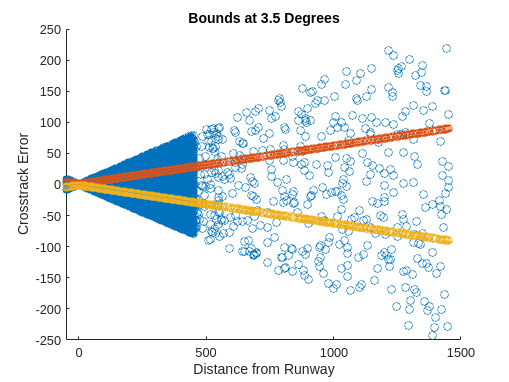


scatter(x, y);
hold on;
% scatter(x_in, y_in);
scatter(x, r + dist_const);
scatter(x, -r - dist_const);
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
title("Bounds at 3.5 Degrees");
hold off;

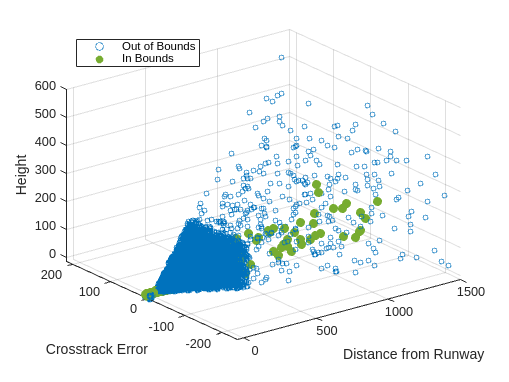


green = [0.4660 0.6740 0.1880];
blue = [0 0.4470 0.7410];
scatter3(x, y, h, 15, blue);
hold on;
% scatter3(x, y, u_bounds);
% scatter3(x, y, l_bounds);
% scatter3(x, r, h);
% scatter3(x, -r, h);
scatter3(x_in, y_in, h_in, 50, green, "filled");
xlabel("Distance from Runway");
ylabel("Crosstrack Error");
zlabel("Height");
legend({"Out of Bounds", "In Bounds"}, 'Location', 'northwest');
hold off;